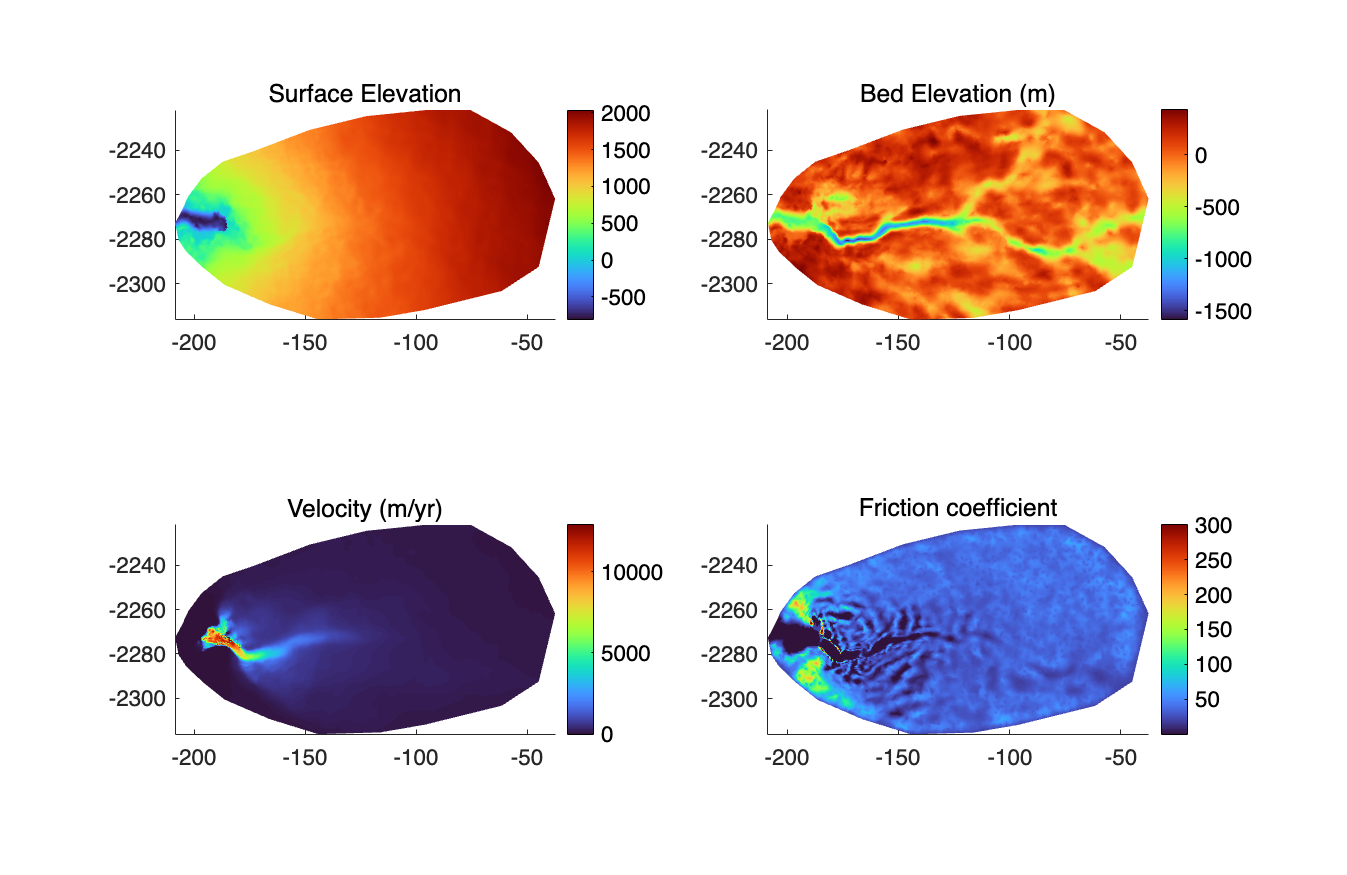

% Load the inversion model of Jakobshavn Isbrae and plot some result parameters
md=loadmodel('/Users/rishi/Desktop/ISSM/examples/Jakobshavn/Jakob_inversion');

plotmodel(md,'data',md.geometry.surface,'title','Surface Elevation',...
'data',md.geometry.base,'title','Bed Elevation (m)',...
'data',md.initialization.vel,'title','Velocity (m/yr)',...
'data',md.friction.coefficient,'title','Friction coefficient',...
'unit#all','km','figposition','fullscreen')

## Coupled SHAKTI-ISSM simulation of Jakobshavn, starting from previous inversion

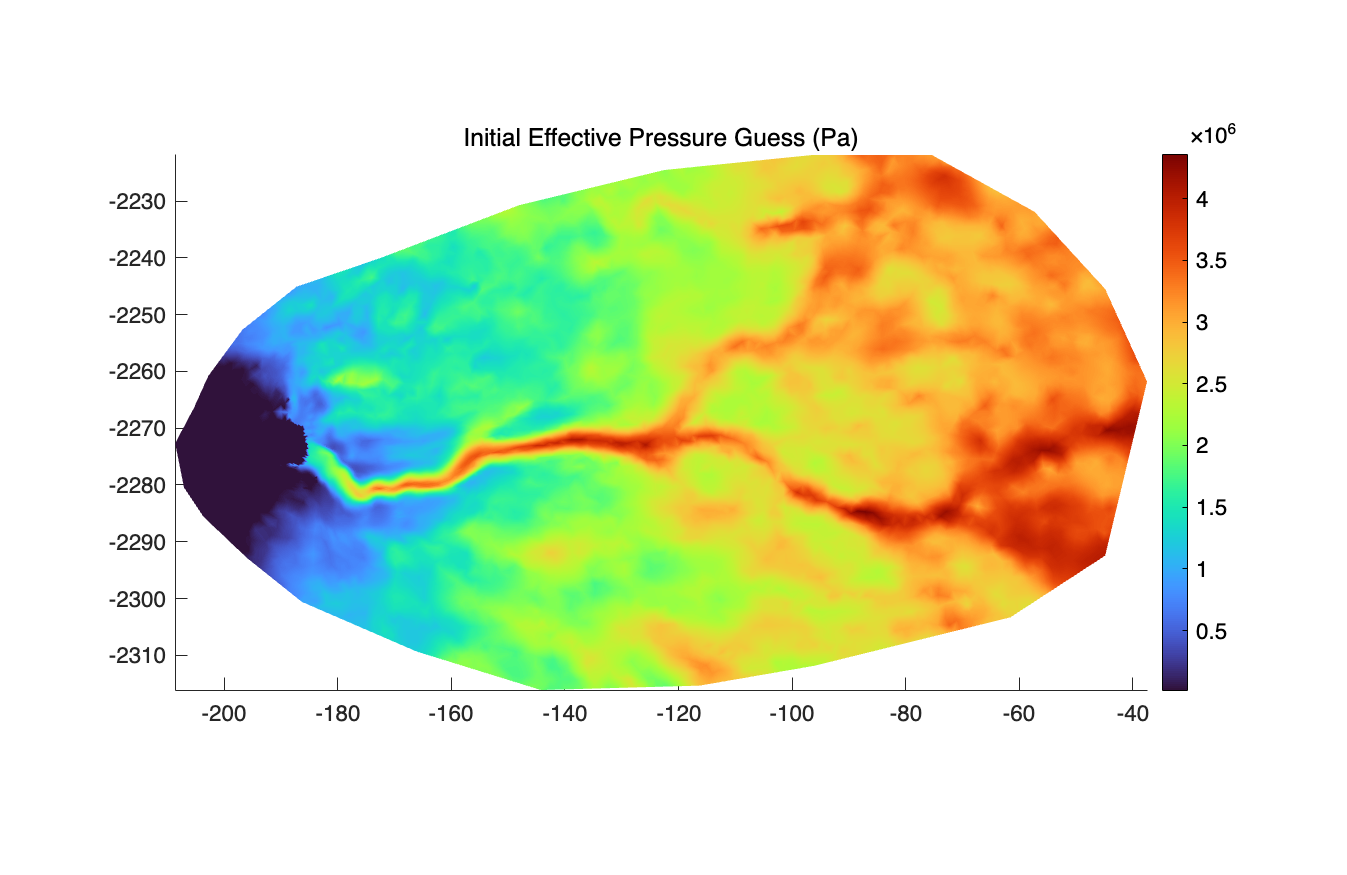

% -------------------------------------------------------------------------------------------------------------------------
% md.hydrology
% 
%    hydrologyshakti solution parameters:
%          head                   :   -- subglacial hydrology water head (m)
%          gap_height             :   -- height of gap separating ice to bed (m)
%          gap_height_min         :   -- minimum allowed gap height (m)
%          gap_height_max         :   -- maximum allowed gap height (m)
%          bump_spacing           :   -- characteristic bedrock bump spacing (m)
%          bump_height            :   -- characteristic bedrock bump height (m)
%          englacial_input        :   -- liquid water input from englacial to subglacial system (m/yr)
%          moulin_input           :   -- liquid water input from moulins (at the vertices) to subglacial system (m^3/s)
%          reynolds               :   -- Reynolds' number
%          neumannflux            :   -- water flux applied along the model boundary (m^2/s)
%          spchead                :   -- water head constraints (NaN means no constraint) (m)
%          relaxation             :   -- under-relaxation coefficient for nonlinear iteration
%          storage                :   -- englacial storage coefficient (void ratio)
%          requested_outputs      :   -- additional outputs requested
%
% -------------------------------------------------------------------------------------------------------------------------


% Turn off inversion first
md.inversion.iscontrol=0;

% HYDROLOGY SPECIFIC PARAMETERIZATION:
md.hydrology=hydrologyshakti(); % Change hydrology class to SHAKTI model

% Next, we initialize the SHAKTI-specific hydrological parameters:
md.hydrology.englacial_input = 0.0*ones(md.mesh.numberofvertices,1); % distributed englacial input to the subglacial system (m/yr)
md.hydrology.head = (0.8*md.materials.rho_ice/md.materials.rho_freshwater) * md.geometry.thickness + md.geometry.base; ...% initial water head such that water pressure is 80% of ice overburden pressure
md.hydrology.gap_height = 0.01*ones(md.mesh.numberofelements,1); % Initial subglacial gap height of 0.01m everywhere
md.hydrology.bump_spacing = 1.0*ones(md.mesh.numberofelements,1); % Typical bed bump bump spacing -- must be non-zero
md.hydrology.bump_height = 0.0*ones(md.mesh.numberofelements,1); % Typical bed bump height -- set to zero to turn off opening by sliding
md.hydrology.reynolds= 1000*ones(md.mesh.numberofelements,1); % Initial Reynolds number (start at Re=1000 everywhere)

% BOUNDARY CONDITIONS
md.hydrology.spchead = NaN(md.mesh.numberofvertices,1);

% Set head=0 for thin ice, everywhere <=10m ice thickness
pos=find(md.geometry.thickness==10);
md.hydrology.spchead(pos)=0;
% Set pressure in fjord equal to hydrostatic pressure of fjord water
pos=find(md.mask.ice_levelset>0);
md.hydrology.spchead(pos)=0;
md.hydrology.moulin_input = zeros(md.mesh.numberofvertices,1); % No moulin inputs
md.hydrology.neumannflux=zeros(md.mesh.numberofelements,1); % No-flux b.c. on domain boundary

% % Deal with terminus b.c. in SHAKTI
% terminus=ContourToNodes(md.mesh.x,md.mesh.y,'Exp/terminus_big.exp',1);
% pos=find(terminus & md.mask.ice_levelset<=0);
% md.hydrology.spchead(pos)=0;

% Coupling and friction
md.transient = deactivateall(md.transient);
md.transient.isstressbalance=1; % 1=Solve for ice velocity, 0=turn off stress balance
md.transient.ishydrology=1;

% Friction and effective pressure
Neff = md.materials.rho_ice*md.constants.g*md.geometry.thickness-md.materials.rho_water*md.constants.g*...
    (md.hydrology.head - md.geometry.base); %Initial effective pressure
md.friction.effective_pressure = Neff;
md.friction.coupling = 4; % Change this to couple (4) /uncouple with prescribed N (3) ***

% Plot the initial effective pressure from the model output
plotmodel(md,'data',md.friction.effective_pressure,'unit','km','title','Initial Effective Pressure Guess (Pa)')

## RUN TRANSIENT SIMULATION

% Change the number of processors according to your machine
md.cluster=generic('np',4);

% Define the time stepping scheme
md.timestepping.time_step = 1*3600/md.constants.yts; % Time step (1 hours in years)
md.timestepping.final_time = 1/365; % Final time (3 days expressed in years) - 24 time steps of 1 hour each
md.settings.output_frequency = 6; % Save results for only every 6 hours (4 results per day)

% Run!
md.verbose.solution=1; % Set to 1 to keep track of time step progress, If set to 0, the model runs silently (useful for long jobs on HPC).
md=solve(md,'Transient');
save Jakob_SHAKTI-hydrology md % save the model output for future use

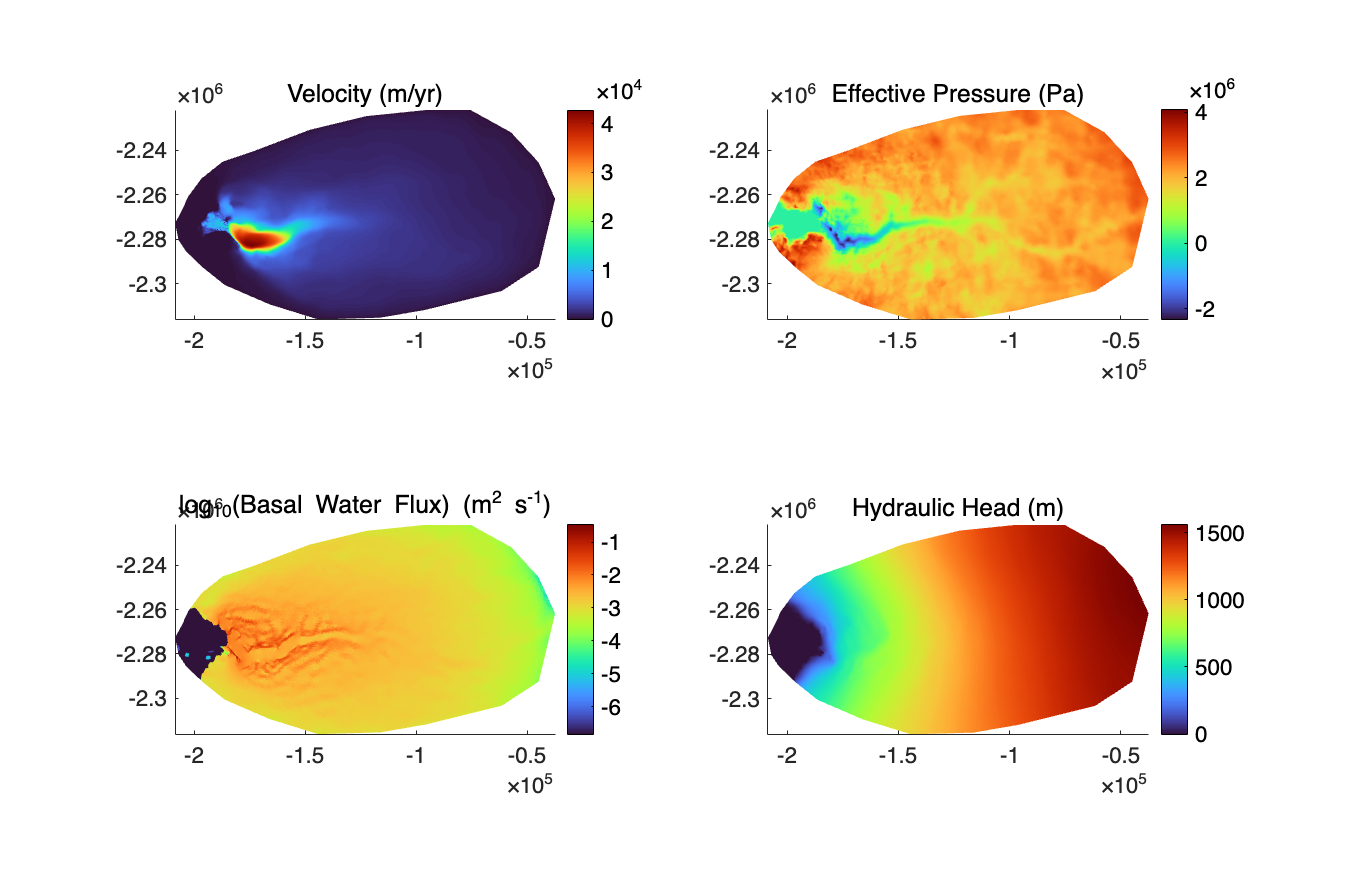

% Plot and Evaluate the end result of the transient simulation
plotmodel(md, ...
    'data', md.results.TransientSolution(end).Vel, ...
    'title', 'Velocity (m/yr)', ...
    'data', md.results.TransientSolution(end).EffectivePressure, ...
    'title', 'Effective Pressure (Pa)', ...
    'data', log10(md.results.TransientSolution(end).HydrologyBasalFlux), ...
    'title', 'log_{10}(Basal Water Flux) (m^2 s^{-1})', ...
    'data', md.results.TransientSolution(end).HydrologyHead, ...
    'title', 'Hydraulic Head (m)','figposition','fullscreen');